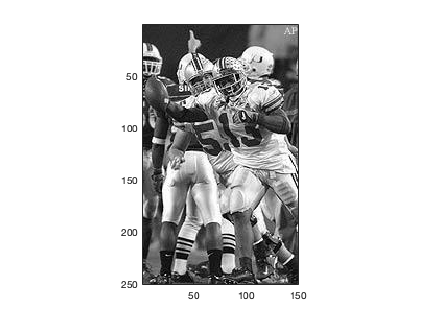

% 1.
grayIm = imread('buckeyes_gray.bmp');
imagesc(grayIm);
axis('image');
colormap('gray');

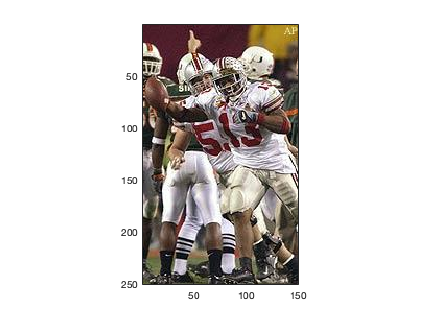

imwrite(grayIm, 'buckeyes_gray.jpg');

rgbIm = imread('buckeyes_rgb.bmp');
imagesc(rgbIm);
axis('image');
imwrite(rgbIm, 'buckeyes_rgb.jpg');

This code read in a bitmap and then saved them to a jpeg file. 

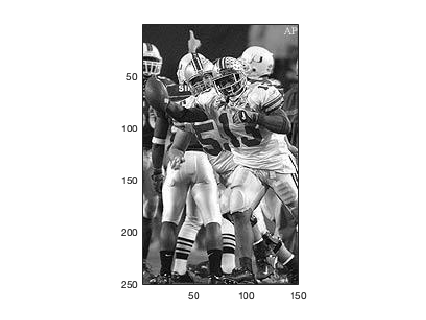

% 2.
grayIm = rgb2gray(rgbIm);
imagesc(grayIm);
axis('image');

imwrite(grayIm, 'buckeyes_converted.jpg')

The converted image looks identical to the given gray image that was read in and displayed in part 1. 

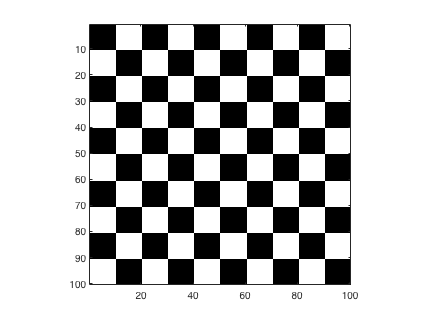

% 3.
zBlock = zeros(10, 10);
oBlock = ones(10, 10) * 255;
pattern = [zBlock oBlock; oBlock zBlock];
checkerIm = repmat(pattern, 5, 5);
imwrite(uint8(checkerIm), 'checkerIm.bmp');
Im = imread('checkerIm.bmp');
imagesc(Im)
colormap('gray')
axis('image');

The checkerboard displayed is a 10 by 10 grid of black and white squares. First a grid of 10x10 black pixels and 10x10 white pixels were made, then they were multiplied 5 times in the x and y directions to create a 100px X 100px checkerboard. 